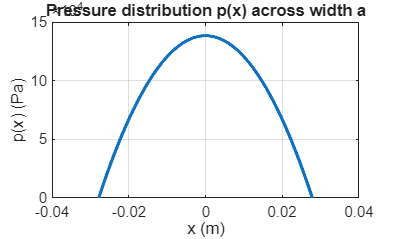

% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;

a_mm = 55.67; % mm kort side kontaktflate
b_mm = 154; % mm Langside kontaktflate
Fz_kg = 80.575; % kg vekt på hjulet
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-31, 31, 1000);   % deg styrevinkel
delta_deg2 = linspace(0,31,1000);

g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g;      % N
x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad

% Pressure Distribution
p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)

plot(x, p, 'LineWidth', 2)
grid on
xlabel('x (m)')
ylabel('p(x) (Pa)')
title('Pressure distribution p(x) across width a')

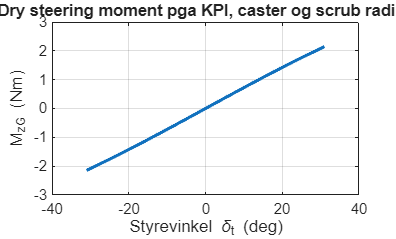


% Gravity based aligning moment
MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta); % Nm

figure
plot(delta_deg, MzG, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment pga KPI, caster og scrub radius')


% Friction based moment
x0 = -a/2;
x1 = a/2;
y0 = -b/2; 
y1 = b/2; 

e0 = 22.36e-3; %m
beta = 10; %degrees

ex = e0*cosd(beta);
ey = e0*sind(beta);
mu = 1.75; %friction coeff

fun = @(x,y) ((6*Fz)/(a^3*b) .* (a/2 - x) .* (a/2 + x)).*(sqrt((ex - x).^2 + (ey - y).^2));

Mzft = mu * integral2(fun, x0, x1, y0, y1);

Mzf = Mzft*cos(sigma)*cos(tau); %Nm
%Mzf = Mzf/1000; %Nm
Mfo = 0.4; %Nm
D = 47.5e-3; %m

Lk = 84.55e-3; %m
theta_tk = linspace(107.55, 84.17,1000); %degrees
theta_tk = deg2rad(theta_tk);
theta_rt = linspace(179.95,179.59,1000); %degrees
theta_rt = deg2rad(theta_rt);
theta_kk = deg2rad(68.54); %degrees
Frt = 1; %N ÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆ
R = D/2; %m
L = Lk .* sin(theta_tk);
Ftt = Frt .* cos(pi-theta_rt);
i = (Ftt .* L .* cos(theta_kk-(pi/2)))/(Frt .* R);

Mz = 2*((Mzf+MzG)./i) + Mfo

Mz =    39.9256   39.9230   39.9203   39.9177   39.9151   39.9124   39.9098   39.9072   39.9046   39.9021   39.8995   39.8969   39.8944   39.8918   39.8893   39.8867   39.8842   39.8817   39.8792   39.8767   39.8742   39.8717   39.8693   39.8668   39.8644   39.8619   39.8595   39.8571   39.8546   39.8522   39.8498   39.8474   39.8451   39.8427   39.8403   39.8380   39.8356   39.8333   39.8310   39.8286   39.8263   39.8240   39.8217   39.8194   39.8172   39.8149   39.8126   39.8104   39.8081   39.8059


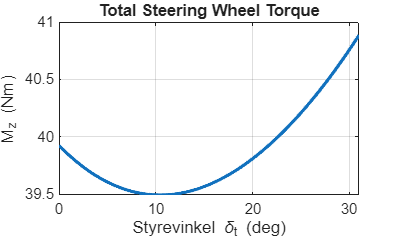

figure
plot(delta_deg2, Mz, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{z} (Nm)')
title('Total Steering Wheel Torque')